**Algorithm for getting Ackerman error**

The purpose of this algorithm is to get the average Ackerman error of a steering system given its dimensions and steering knuckle angle. 

The steering mechanism that will be used is rack-pinion.

A commercial vehicle rack will be chosen based on our needs. Some of the current options are: 

1) 

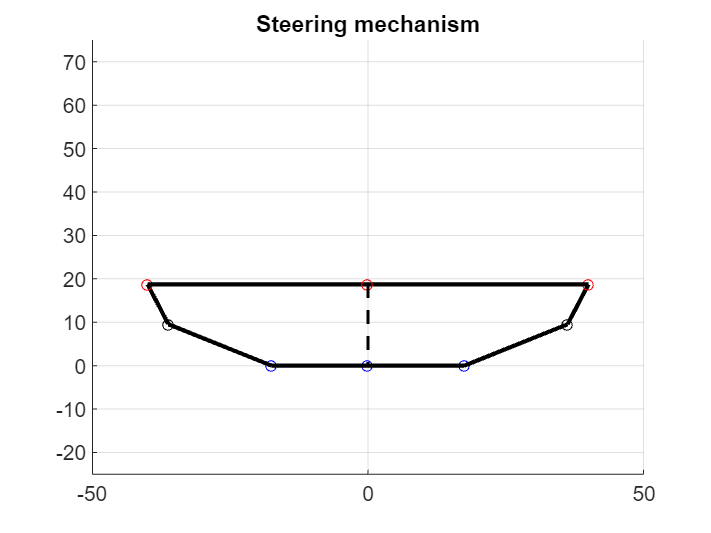

% Dimensions (cm)
k_arm = 10;     % arm connected to knuckle 
tie_rod = 21;   % intermediate arm
rack = 35;
track = 80;    % wheelbase width
d = 18.72;     % Distance between rack & front chassis

% Angles
gamma_l = 27; gamma_r = 27; % Angles between tie rod and rack projection

figure(); title('Steering mechanism')
hold on; grid on; xlim([-50 50]); ylim([-25 75]);
plot(0, 0, 'bo', MarkerSize=5);
% Rack
plot(-rack/2, 0, 'bo', MarkerSize=5);
plot(rack/2, 0, 'bo', MarkerSize=5);
plot([-rack/2 rack/2], [0 0], 'k', LineWidth=2); % Unir puntos
% Tie rods
left_tie = [-tie_rod * cos(deg2rad(gamma_l)) - rack/2, tie_rod * sin(deg2rad(gamma_l))];
right_tie = [tie_rod * cos(deg2rad(gamma_r)) + rack/2, tie_rod * sin(deg2rad(gamma_r))];
plot(left_tie(1), left_tie(2), 'ko', MarkerSize=5);
plot(right_tie(1), right_tie(2), 'ko', MarkerSize=5);
plot([left_tie(1), -rack/2], [left_tie(2), 0], 'k', LineWidth=2);
plot([right_tie(1), rack/2], [right_tie(2), 0], 'k', LineWidth=2);
% Knuckle arms
plot([left_tie(1), -track/2], [left_tie(2), d], 'k', LineWidth=2);
plot([right_tie(1), track/2], [right_tie(2), d], 'k', LineWidth=2);
% Track
plot(-track/2, d, 'ro', MarkerSize=5);
plot(track/2, d, 'ro', MarkerSize=5);
plot([-track/2, track/2], [d,d], 'k', LineWidth=2);
% Dist
plot(0, d, 'ro', MarkerSize=5);
plot([0, 0], [d, 0], 'k', LineWidth=1.5, LineStyle='--');